# Import data from text file

Script for importing data from the following text file:

filenametrain =  'C:\Users\Resma and Redwan\OneDrive - University of Georgia\Spring 2020\CSCI 8960 Privacy Perserving Data Mining\projectdir\fashion-mnist_train.csv';
filenametest = 'C:\Users\Resma and Redwan\OneDrive - University of Georgia\Spring 2020\CSCI 8960 Privacy Perserving Data Mining\projectdir\fashion-mnist_test.csv';

Auto-generated by MATLAB on 16-Apr-2020 18:18:34

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 785);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["label", "pixel1", "pixel2", "pixel3", "pixel4", "pixel5", "pixel6", "pixel7", "pixel8", "pixel9", "pixel10", "pixel11", "pixel12", "pixel13", "pixel14", "pixel15", "pixel16", "pixel17", "pixel18", "pixel19", "pixel20", "pixel21", "pixel22", "pixel23", "pixel24", "pixel25", "pixel26", "pixel27", "pixel28", "pixel29", "pixel30", "pixel31", "pixel32", "pixel33", "pixel34", "pixel35", "pixel36", "pixel37", "pixel38", "pixel39", "pixel40", "pixel41", "pixel42", "pixel43", "pixel44", "pixel45", "pixel46", "pixel47", "pixel48", "pixel49", "pixel50", "pixel51", "pixel52", "pixel53", "pixel54", "pixel55", "pixel56", "pixel57", "pixel58", "pixel59", "pixel60", "pixel61", "pixel62", "pixel63", "pixel64", "pixel65", "pixel66", "pixel67", "pixel68", "pixel69", "pixel70", "pixel71", "pixel72", "pixel73", "pixel74", "pixel75", "pixel76", "pixel77", "pixel78", "pixel79", "pixel80", "pixel81", "pixel82", "pixel83", "pixel84", "pixel85", "pixel86", "pixel87", "pixel88", "pixel89", "pixel90", "pixel91", "pixel92", "pixel93", "pixel94", "pixel95", "pixel96", "pixel97", "pixel98", "pixel99", "pixel100", "pixel101", "pixel102", "pixel103", "pixel104", "pixel105", "pixel106", "pixel107", "pixel108", "pixel109", "pixel110", "pixel111", "pixel112", "pixel113", "pixel114", "pixel115", "pixel116", "pixel117", "pixel118", "pixel119", "pixel120", "pixel121", "pixel122", "pixel123", "pixel124", "pixel125", "pixel126", "pixel127", "pixel128", "pixel129", "pixel130", "pixel131", "pixel132", "pixel133", "pixel134", "pixel135", "pixel136", "pixel137", "pixel138", "pixel139", "pixel140", "pixel141", "pixel142", "pixel143", "pixel144", "pixel145", "pixel146", "pixel147", "pixel148", "pixel149", "pixel150", "pixel151", "pixel152", "pixel153", "pixel154", "pixel155", "pixel156", "pixel157", "pixel158", "pixel159", "pixel160", "pixel161", "pixel162", "pixel163", "pixel164", "pixel165", "pixel166", "pixel167", "pixel168", "pixel169", "pixel170", "pixel171", "pixel172", "pixel173", "pixel174", "pixel175", "pixel176", "pixel177", "pixel178", "pixel179", "pixel180", "pixel181", "pixel182", "pixel183", "pixel184", "pixel185", "pixel186", "pixel187", "pixel188", "pixel189", "pixel190", "pixel191", "pixel192", "pixel193", "pixel194", "pixel195", "pixel196", "pixel197", "pixel198", "pixel199", "pixel200", "pixel201", "pixel202", "pixel203", "pixel204", "pixel205", "pixel206", "pixel207", "pixel208", "pixel209", "pixel210", "pixel211", "pixel212", "pixel213", "pixel214", "pixel215", "pixel216", "pixel217", "pixel218", "pixel219", "pixel220", "pixel221", "pixel222", "pixel223", "pixel224", "pixel225", "pixel226", "pixel227", "pixel228", "pixel229", "pixel230", "pixel231", "pixel232", "pixel233", "pixel234", "pixel235", "pixel236", "pixel237", "pixel238", "pixel239", "pixel240", "pixel241", "pixel242", "pixel243", "pixel244", "pixel245", "pixel246", "pixel247", "pixel248", "pixel249", "pixel250", "pixel251", "pixel252", "pixel253", "pixel254", "pixel255", "pixel256", "pixel257", "pixel258", "pixel259", "pixel260", "pixel261", "pixel262", "pixel263", "pixel264", "pixel265", "pixel266", "pixel267", "pixel268", "pixel269", "pixel270", "pixel271", "pixel272", "pixel273", "pixel274", "pixel275", "pixel276", "pixel277", "pixel278", "pixel279", "pixel280", "pixel281", "pixel282", "pixel283", "pixel284", "pixel285", "pixel286", "pixel287", "pixel288", "pixel289", "pixel290", "pixel291", "pixel292", "pixel293", "pixel294", "pixel295", "pixel296", "pixel297", "pixel298", "pixel299", "pixel300", "pixel301", "pixel302", "pixel303", "pixel304", "pixel305", "pixel306", "pixel307", "pixel308", "pixel309", "pixel310", "pixel311", "pixel312", "pixel313", "pixel314", "pixel315", "pixel316", "pixel317", "pixel318", "pixel319", "pixel320", "pixel321", "pixel322", "pixel323", "pixel324", "pixel325", "pixel326", "pixel327", "pixel328", "pixel329", "pixel330", "pixel331", "pixel332", "pixel333", "pixel334", "pixel335", "pixel336", "pixel337", "pixel338", "pixel339", "pixel340", "pixel341", "pixel342", "pixel343", "pixel344", "pixel345", "pixel346", "pixel347", "pixel348", "pixel349", "pixel350", "pixel351", "pixel352", "pixel353", "pixel354", "pixel355", "pixel356", "pixel357", "pixel358", "pixel359", "pixel360", "pixel361", "pixel362", "pixel363", "pixel364", "pixel365", "pixel366", "pixel367", "pixel368", "pixel369", "pixel370", "pixel371", "pixel372", "pixel373", "pixel374", "pixel375", "pixel376", "pixel377", "pixel378", "pixel379", "pixel380", "pixel381", "pixel382", "pixel383", "pixel384", "pixel385", "pixel386", "pixel387", "pixel388", "pixel389", "pixel390", "pixel391", "pixel392", "pixel393", "pixel394", "pixel395", "pixel396", "pixel397", "pixel398", "pixel399", "pixel400", "pixel401", "pixel402", "pixel403", "pixel404", "pixel405", "pixel406", "pixel407", "pixel408", "pixel409", "pixel410", "pixel411", "pixel412", "pixel413", "pixel414", "pixel415", "pixel416", "pixel417", "pixel418", "pixel419", "pixel420", "pixel421", "pixel422", "pixel423", "pixel424", "pixel425", "pixel426", "pixel427", "pixel428", "pixel429", "pixel430", "pixel431", "pixel432", "pixel433", "pixel434", "pixel435", "pixel436", "pixel437", "pixel438", "pixel439", "pixel440", "pixel441", "pixel442", "pixel443", "pixel444", "pixel445", "pixel446", "pixel447", "pixel448", "pixel449", "pixel450", "pixel451", "pixel452", "pixel453", "pixel454", "pixel455", "pixel456", "pixel457", "pixel458", "pixel459", "pixel460", "pixel461", "pixel462", "pixel463", "pixel464", "pixel465", "pixel466", "pixel467", "pixel468", "pixel469", "pixel470", "pixel471", "pixel472", "pixel473", "pixel474", "pixel475", "pixel476", "pixel477", "pixel478", "pixel479", "pixel480", "pixel481", "pixel482", "pixel483", "pixel484", "pixel485", "pixel486", "pixel487", "pixel488", "pixel489", "pixel490", "pixel491", "pixel492", "pixel493", "pixel494", "pixel495", "pixel496", "pixel497", "pixel498", "pixel499", "pixel500", "pixel501", "pixel502", "pixel503", "pixel504", "pixel505", "pixel506", "pixel507", "pixel508", "pixel509", "pixel510", "pixel511", "pixel512", "pixel513", "pixel514", "pixel515", "pixel516", "pixel517", "pixel518", "pixel519", "pixel520", "pixel521", "pixel522", "pixel523", "pixel524", "pixel525", "pixel526", "pixel527", "pixel528", "pixel529", "pixel530", "pixel531", "pixel532", "pixel533", "pixel534", "pixel535", "pixel536", "pixel537", "pixel538", "pixel539", "pixel540", "pixel541", "pixel542", "pixel543", "pixel544", "pixel545", "pixel546", "pixel547", "pixel548", "pixel549", "pixel550", "pixel551", "pixel552", "pixel553", "pixel554", "pixel555", "pixel556", "pixel557", "pixel558", "pixel559", "pixel560", "pixel561", "pixel562", "pixel563", "pixel564", "pixel565", "pixel566", "pixel567", "pixel568", "pixel569", "pixel570", "pixel571", "pixel572", "pixel573", "pixel574", "pixel575", "pixel576", "pixel577", "pixel578", "pixel579", "pixel580", "pixel581", "pixel582", "pixel583", "pixel584", "pixel585", "pixel586", "pixel587", "pixel588", "pixel589", "pixel590", "pixel591", "pixel592", "pixel593", "pixel594", "pixel595", "pixel596", "pixel597", "pixel598", "pixel599", "pixel600", "pixel601", "pixel602", "pixel603", "pixel604", "pixel605", "pixel606", "pixel607", "pixel608", "pixel609", "pixel610", "pixel611", "pixel612", "pixel613", "pixel614", "pixel615", "pixel616", "pixel617", "pixel618", "pixel619", "pixel620", "pixel621", "pixel622", "pixel623", "pixel624", "pixel625", "pixel626", "pixel627", "pixel628", "pixel629", "pixel630", "pixel631", "pixel632", "pixel633", "pixel634", "pixel635", "pixel636", "pixel637", "pixel638", "pixel639", "pixel640", "pixel641", "pixel642", "pixel643", "pixel644", "pixel645", "pixel646", "pixel647", "pixel648", "pixel649", "pixel650", "pixel651", "pixel652", "pixel653", "pixel654", "pixel655", "pixel656", "pixel657", "pixel658", "pixel659", "pixel660", "pixel661", "pixel662", "pixel663", "pixel664", "pixel665", "pixel666", "pixel667", "pixel668", "pixel669", "pixel670", "pixel671", "pixel672", "pixel673", "pixel674", "pixel675", "pixel676", "pixel677", "pixel678", "pixel679", "pixel680", "pixel681", "pixel682", "pixel683", "pixel684", "pixel685", "pixel686", "pixel687", "pixel688", "pixel689", "pixel690", "pixel691", "pixel692", "pixel693", "pixel694", "pixel695", "pixel696", "pixel697", "pixel698", "pixel699", "pixel700", "pixel701", "pixel702", "pixel703", "pixel704", "pixel705", "pixel706", "pixel707", "pixel708", "pixel709", "pixel710", "pixel711", "pixel712", "pixel713", "pixel714", "pixel715", "pixel716", "pixel717", "pixel718", "pixel719", "pixel720", "pixel721", "pixel722", "pixel723", "pixel724", "pixel725", "pixel726", "pixel727", "pixel728", "pixel729", "pixel730", "pixel731", "pixel732", "pixel733", "pixel734", "pixel735", "pixel736", "pixel737", "pixel738", "pixel739", "pixel740", "pixel741", "pixel742", "pixel743", "pixel744", "pixel745", "pixel746", "pixel747", "pixel748", "pixel749", "pixel750", "pixel751", "pixel752", "pixel753", "pixel754", "pixel755", "pixel756", "pixel757", "pixel758", "pixel759", "pixel760", "pixel761", "pixel762", "pixel763", "pixel764", "pixel765", "pixel766", "pixel767", "pixel768", "pixel769", "pixel770", "pixel771", "pixel772", "pixel773", "pixel774", "pixel775", "pixel776", "pixel777", "pixel778", "pixel779", "pixel780", "pixel781", "pixel782", "pixel783", "pixel784"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
fashionmnisttrain = readtable(filenametrain, opts);
fashionmnisttest = readtable( filenametest , opts);


## Convert to output type

fashionmnisttrain = table2array(fashionmnisttrain);
fashionmnisttest = table2array(fashionmnisttest);


## Clear temporary variables

clear opts;

Seperate Training data and label

X_train = fashionmnisttrain(:,2:end);
y_train = fashionmnisttrain(:,1);
X_test = fashionmnisttest(:,2:end);
y_test = fashionmnisttest(:,1);

y_train = categorical(y_train);
y_test = categorical(y_test);

for i= 1:size(X_train,1)
    XTrain(:,1,1,i) = X_train(i,:);
end
for i= 1:size(X_test,1)
    XTest(:,1,1,i) = X_test(i,:);
end

XValidation = XTest;
YValidation = y_test;

layers = [
    imageInputLayer([784 1 1],"Name","imageinput")
    fullyConnectedLayer(1000,"Name","fc_1")
    fullyConnectedLayer(1000,"Name","fc_2")
    fullyConnectedLayer(10,"Name","fc_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];


options = trainingOptions('sgdm', ...
    'ValidationData',{XValidation,YValidation}, ...
    'InitialLearnRate', 1e-4, ...
    'Verbose',false, ...
    'Plots','training-progress');

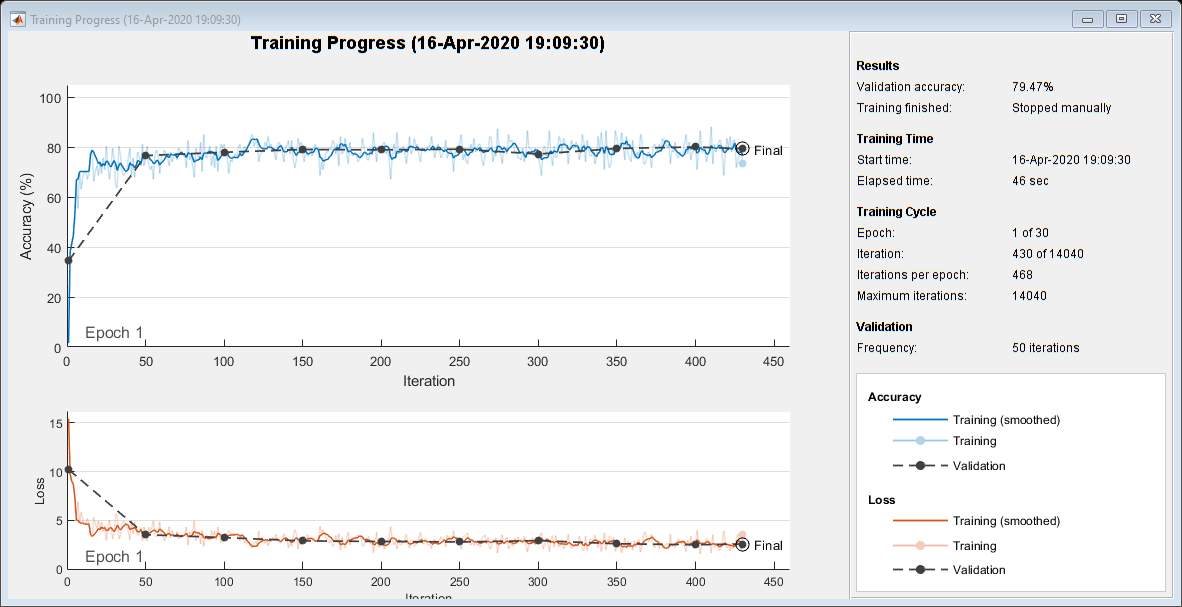

net = trainNetwork(XTrain,y_train,layers,options);